# Distillate Composition Control

Over 40,000 distillation columns in the U.S. consume 40-60% of the total energy in the petrochemical industry and 6% of the total U.S. energy usage. Reducing distillation energy usage would have a major impact on energy independence, greenhouse gas emissions, and give a competitive advantage to any manufacturer that is better able to implement improvements.

The objective of this exercise is to maintain an overhead mole fraction for the light component in a binary distillation column that separates cyclohexane and n-heptane. The nominal steady state for the column is a reflux ratio at 3.0 with an allowable range from 1.0 to 10.0. This reflux ratio produces a cyclohexane product with a purity of5  0.93(mole fraction), but the target composition is 0.970 with an allowable range of 0.960 to 0.980. The objective is to design a PID controller to meet this target value and stay within the specified product range.

**Manipulated Variable:** Reflux Ratio: RR (Ratio of distillate flowrate returning to the column divided by the flowrate of the product leaving)

**Controlled Variable:** Distillate composition ($x_d$) mole fraction

**Measured Disturbances:** (1) Feed flow rate, (2) Feed composition (mole fraction)

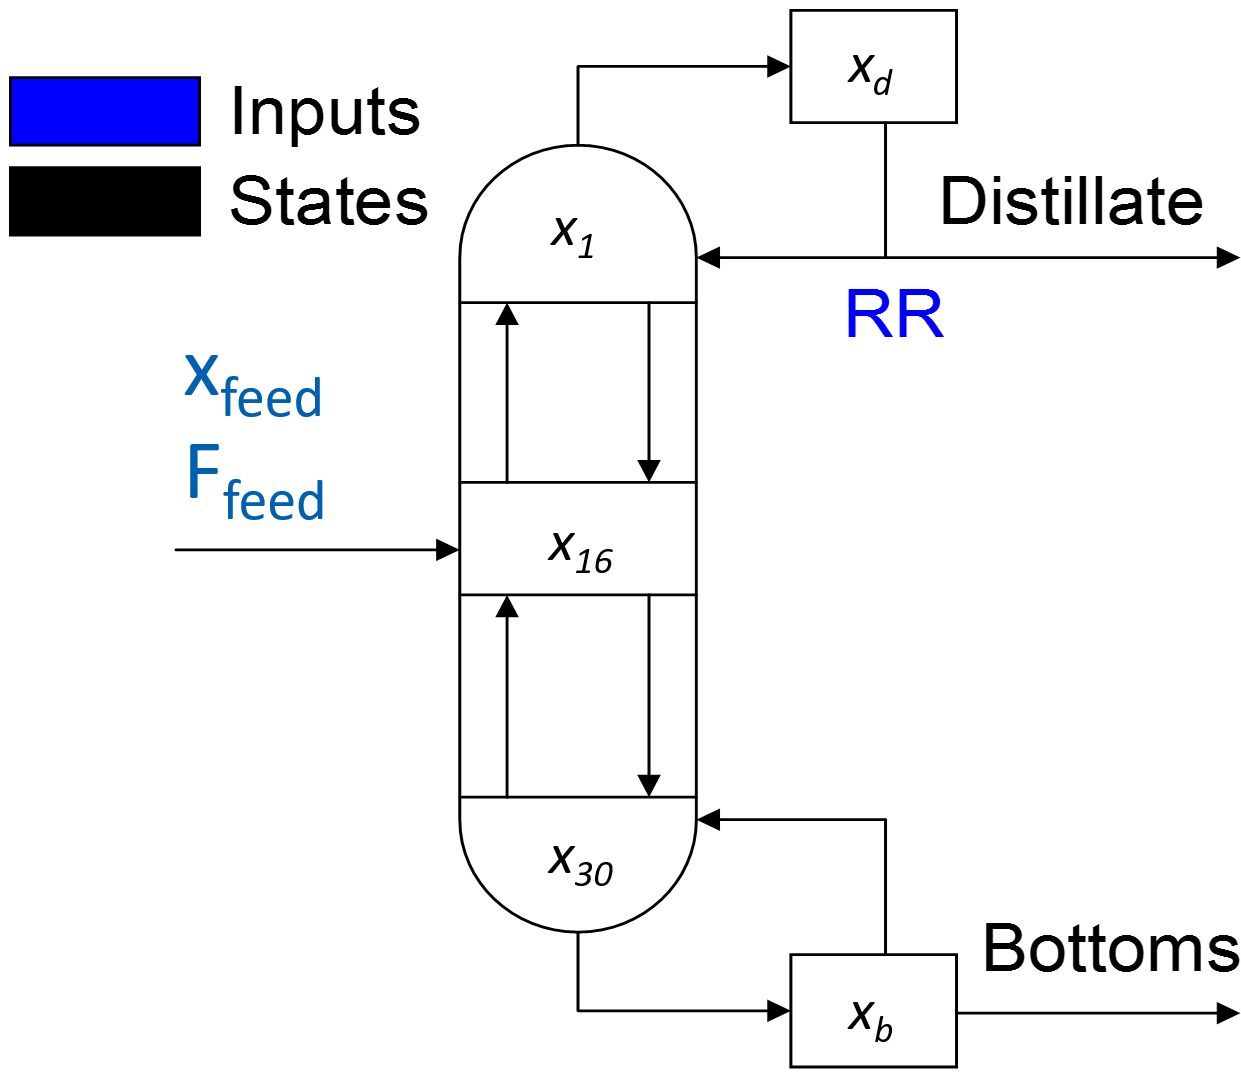

## Determine Steady State Conditions

Report the design set point and controller bias $u_{bias}$ value for the controller.

## Estimate Model

Perform a doublet test and use the dynamic response data to [**estimate a first order plus dead time (FOPDT) model**](https://apmonitor.com/pdc/index.php/Main/FirstOrderOptimization).

clc; clear all; close all;

% Steady State Initial Conditions for the 32 states
x_ss =[0.935,0.900,0.862,0.821,0.779,0.738,...
0.698,0.661,0.628,0.599,0.574,0.553,0.535,0.521,...
0.510,0.501,0.494,0.485,0.474,0.459,0.441,0.419,...
0.392,0.360,0.324,0.284,0.243,0.201,0.161,0.125,...
0.092,0.064];
x0 = x_ss;

% Steady State Initial Condition
rr_ss = 3.0;

% Time Interval (min)
t = linspace(0,50,500);

% Store results for plotting
xd = ones(1,length(t)) * x_ss(1);
rr = ones(1,length(t)) * rr_ss;
ff = ones(1,length(t));
xf = ones(1,length(t)) * 0.5;

% Step in reflux ratio
rr(10:end) = 5.0;
rr(180:end) = 3.5;
rr(360:end) = 4.0;

for i=1:length(t)-1
    ts = [t(i),t(i+1)];
    [~,y] = ode45(@(t,y) distill(t,y,rr(i),ff(i),xf(i)),ts,x0);
    xd(i+1) = y(end,1);
    x0 = y(end,:);
end
% Construct results and save data file
% Column 1 = time
% Column 2 = reflux ratio
% Column 3 = distillate composition
data = vertcat(vertcat(t,rr),xd).';


subplot(2,1,1);
plot(t,rr,'b--','LineWidth',3);
ylabel('RR');
legend({'Reflux Ratio'});

subplot(2,1,2);
plot(t,xd,'r-',"LineWidth",3); hold off
ylabel('x_d (mol/L)');
legend({'Distillate Composition'});
xlabel('Time (hr)');

## Obtain PID Parameters

Use the FOPDT model values in the [**IMC tuning correlation**](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative) to compute the tuning constants $K_c,\tau_I,$ and $\tau_D$. Specify the sign, magnitude, and units of each.

% initialize inputs
ns = length(t);
yp0 = xd(1);
dt = t(2) - t(1);
u0 = rr(1);
uf = griddedInterpolant(t,rr);
yp = xd;

% initial guesses
xi = zeros(1,3);
xi(1) = 0.03; % Km
xi(2) = 4; % taum
xi(3) = 0.1; % thetam

% show initial objective
fprintf('Initial SSE Objective: %.1f', objective(xi,ns,yp0,uf,dt,u0,yp))

% optimize Km, taum, thetam
solution = fminsearch(@(x) objective(x,ns,yp0,uf,dt,u0,yp),xi,optimset('MaxIter',100,'PlotFcns','optimplotfval'));
Kp = solution(1);
taup = solution(2);
thetap = solution(3);
xs = [Kp taup thetap];    
fprintf('Final SSE Objective: %.1f',objective(xs,ns,yp0,uf,dt,u0,yp));

fprintf('Kp: %.4f', Kp)
fprintf('Taup: %.4f',taup)
fprintf('Thetap: %.4f',thetap)

% plot
y_model = sim_model(xs,ns,yp0,uf,dt,u0);

clf
subplot(2, 1, 1)
plot(t, xd, 'ro', 'DisplayName','Measured Data');hold on
plot(t, y_model, 'b-', 'DisplayName','FOPDT Fit');hold off
xlabel('Time (hr)');
ylabel('xd');
legend();

subplot(2, 1, 2);
plot(t, rr);
xlabel('time (hr)');
ylabel('Reflux ratio');

## Implement PID Controller

Using the design set point, bias, and controller gain, implement the [**PID controller**](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative). Generate a plot showing the performance of the controller in tracking the set point.

u_bias = 3.0;

% moderate tuning
tauc = max(taup, 8 * thetap);
Kc =  60 % 1/Kp * (taup + .5 * thetap) / (tauc + .5 * thetap);
tauI = .5 % taup + .5 * thetap;
tauD = 0;

fprintf('Kc: %.4f',Kc)
fprintf('tauI: %.4f',tauI)
fprintf('tauD: %.4f',tauD)

ns =  1001
xd = ones(1,ns) * x_ss(1);
rr = ones(1,ns) * rr_ss;
ff = ones(1,ns);
xf = ones(1,ns) * 0.5;
xf(500:end) = 0.45;

t = linspace(0,(ns-1)/10, ns)

% storage for recording values
op = ones(1,ns)*3.0;  % controller output
pv = ones(1,ns)*0.935;  % process variable
e = zeros(1,ns);   % error
ie = zeros(1,ns);  % integral of the error
dpv = zeros(1,ns); % derivative of the pv
P = zeros(1,ns);   % proportional
I = zeros(1,ns);   % integral
D = zeros(1,ns);   % derivative
sp = ones(1,ns)*0.94;  % set point
sp(100:end) = 0.97;

% Steady State Initial Conditions for the 32 states
x_ss =[0.935,0.900,0.862,0.821,0.779,0.738,...
0.698,0.661,0.628,0.599,0.574,0.553,0.535,0.521,...
0.510,0.501,0.494,0.485,0.474,0.459,0.441,0.419,...
0.392,0.360,0.324,0.284,0.243,0.201,0.161,0.125,...
0.092,0.064];
x0 = x_ss;

% Upper and Lower limits on OP
op_hi = 100.0;
op_lo = 1.0;



## Set Point Changes

Fine tune the controller gain by trial and error and search for the *best* parameters that balance speed with oscillatory behavior when tracking this set point from 0.935 to 0.970. Remember that as the designer, define what constitutes *best* performance. As well as generating a plot with final tuning, explain what criteria you is used to define *best*.

## Disturbance Rejection

Introduce a disturbance in the feed after 50 minutes by changing the mole fraction from 0.50 to 0.42. Tune the controller to stay within the desired product range given this disturbance. If the controller isn't able to keep within the desirable range, discuss if it is possible to improve the control.

## Distillation Simulation Code

Use the open loop simulation code as a starting point for the problem. There are 30 trays, 1 reboiler, and 1 condenser for this simulation. The 32 states are updated with every cycle of the simulation loop but only the distillate composition is measured.

## Distillation Model

function xdot = distill(~,x,rr,Feed,x_Feed)
    % Inputs (3):
    % Reflux ratio is the Manipulated variable
    % Reflux Ratio (L/D)
    %rr = p(1);
    % Disturbance variables (DV)
    % Feed Flowrate (mol/min)
    %Feed = p(2);

    % Mole Fraction of Feed
    %x_Feed = p(3);

    % States (32):
    % x(0) - Reflux Drum Liquid Mole Fraction of Component A
    % x(1) - Tray 1 - Liquid Mole Fraction of Component A
    % .
    % .
    % .
    % x(16) - Tray 16 - Liquid Mole Fraction of Component A (Feed)
    % .
    % .
    % .
    % x(30) - Tray 30 - Liquid Mole Fraction of Component A
    % x(31) - Reboiler Liquid Mole Fraction of Component A

    % Parameters
    % Distillate Flowrate (mol/min)
    D=0.5*Feed;
    % Flowrate of the Liquid in the Rectification Section (mol/min)
    L=rr*D;
    % Vapor Flowrate in the Column (mol/min)
    V=L+D;
    % Flowrate of the Liquid in the Stripping Section (mol/min)
    FL=Feed+L;
    % Relative Volatility = (yA/xA)/(yB/xB) = KA/KB = alpha(A,B)
    vol=1.6;
    % Total Molar Holdup in the Condenser
    atray=0.25;
    % Total Molar Holdup on each Tray
    acond=0.5;
    % Total Molar Holdup in the Reboiler
    areb=1.0;
    % Vapor Mole Fractions of Component A
    % From the equilibrium assumption and mole balances
    % 1) vol = (yA/xA) / (yB/xB)
    % 2) xA + xB = 1
    % 3) yA + yB = 1
    y = zeros(1,length(x));
    for i=1:32
        y(i) = x(i) * vol/(1.0+(vol-1.0)*x(i));      
    end

    % Compute xdot
    xdot = zeros(1,length(x));
    xdot(1) = 1/acond*V*(y(2)-x(1));
    for i=2:16
        xdot(i) = 1.0/atray*(L*(x(i-1)-x(i))-V*(y(i)-y(i+1)));
    end
    xdot(16) = 1/atray*(Feed*x_Feed+L*x(15)-FL*x(16)-V*(y(16)-y(17)));
    for i=17:31
        xdot(i) = 1.0/atray*(FL*(x(i-1)-x(i))-V*(y(i)-y(i+1)));
    end
    xdot(32) = 1/areb*(FL*x(30)-(Feed-D)*x(31)-V*y(31));
    xdot = xdot.';
end

## 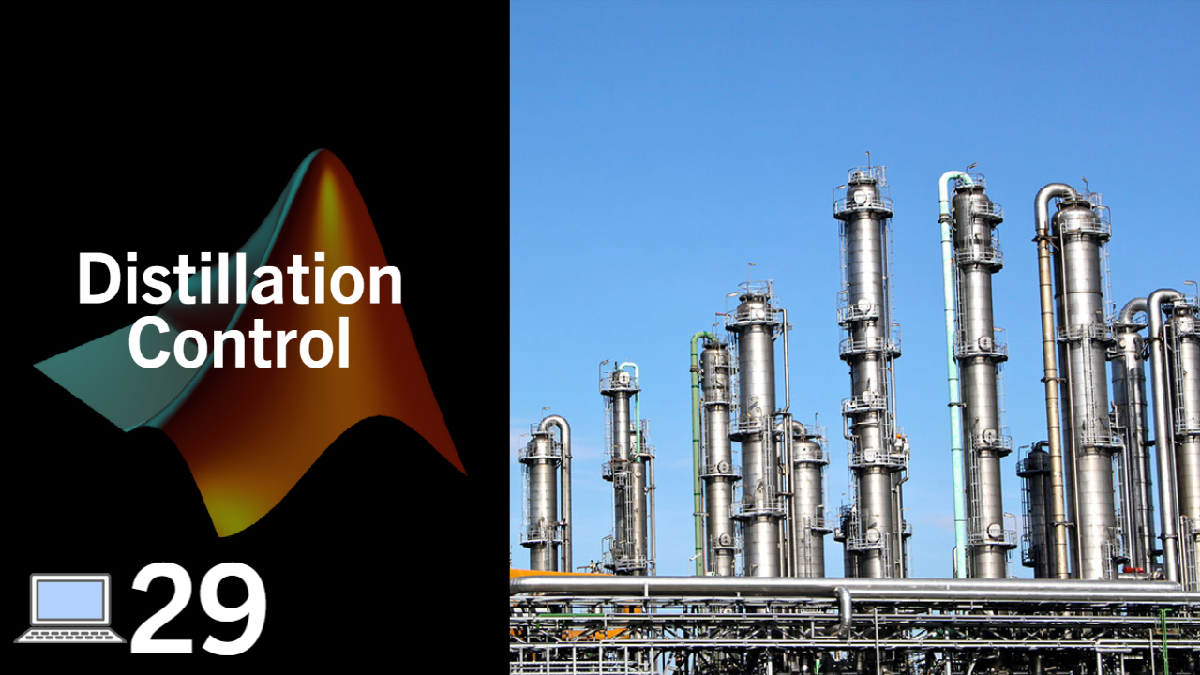

### [View Solution](https://youtu.be/i6TfjICsvEA)

## FOPDT Model

% define FOPDT model
function dydt = fopdt(t,y,uf,Km,taum,thetam,yp0,u0)
    % arguments
    %  y      = output
    %  t      = time
    %  uf     = input linear function (for time shift) (sp interpolated)
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model time constant
    % time-shift u
    try
        if (t-thetam) <= 0
            um = uf(0.0);
        else
            um = uf(t-thetam);
        end
    catch
        um = u0;
    end

    % calculate derivative
    dydt = (-(y-yp0) + Km * (um-u0))/taum;
end

## Simulate FOPDT Model

% simulate FOPDT model with x=[Km,taum,thetam]
function ym = sim_model(x, ns, yp0, uf, dt,u0)
    % input arguments
    Km = x(1);
    taum = x(2);
    thetam = x(3);
    % storage for model values
    ym = zeros(1,ns);  % model
    % initial condition
    ym(1) = yp0;
    % loop through time steps    
    for i = 1:ns-1
        ts = [dt*i,dt*(i+1)];
        [~,y1] = ode45(@(t,y) fopdt(t,y,uf,Km,taum,thetam,yp0,u0),ts,ym(i));
        ym(i+1) = y1(end,:);
    end
end

## Simulation Objective Function

% define objective
function obj = objective(x, ns, yp0, uf, dt, u0, yp)
    % simulate model
    ym = sim_model(x, ns, yp0, uf, dt, u0);
    % calculate objective
    obj = 0.0;
    for i=1:length(ym)
        obj = obj + (ym(i)*100-yp(i)*100)^2;
    end
end